# **Variables**

clear
clc

no_of_bits = 10000;
vcc = 1.2;
gnd = 0;
ts = 0.01;
t = 0 : ts : 10000 - ts;
sigma = linspace(0,vcc,10);

# **Uni-Polar_NRZ**

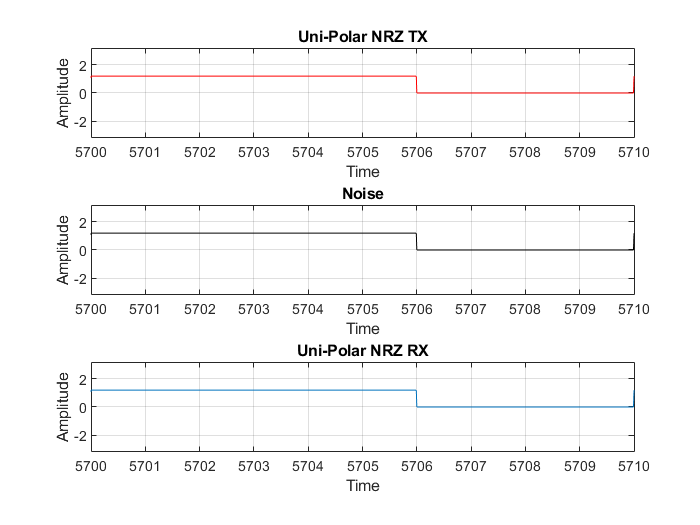

ERROR_Percentage = 0

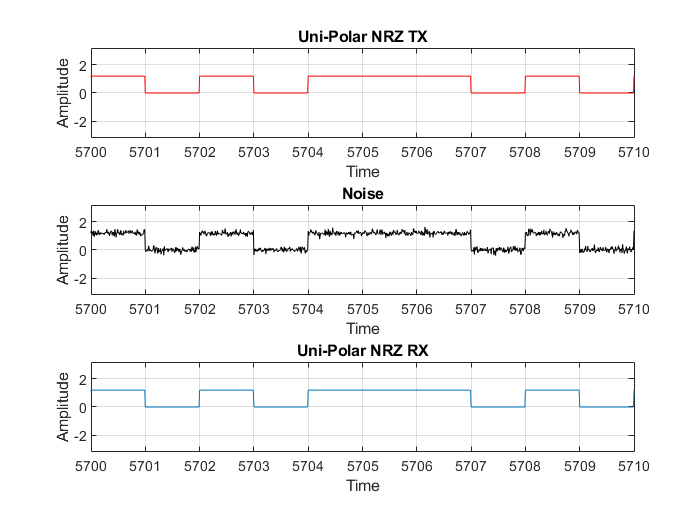

ERROR_Percentage = 0

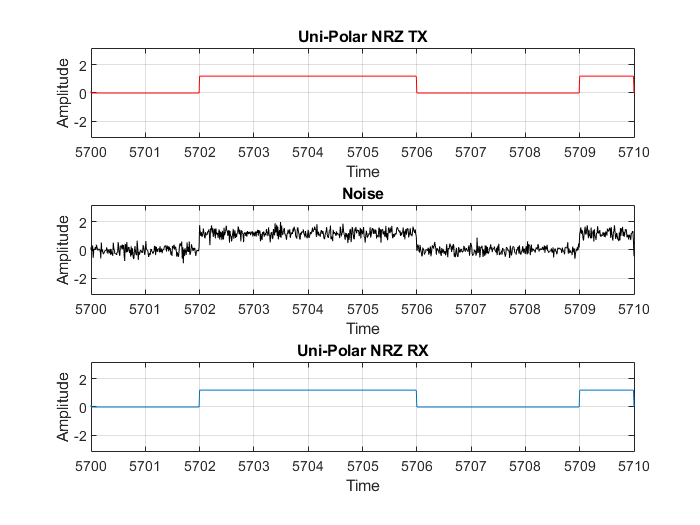

ERROR_Percentage = 1.4900

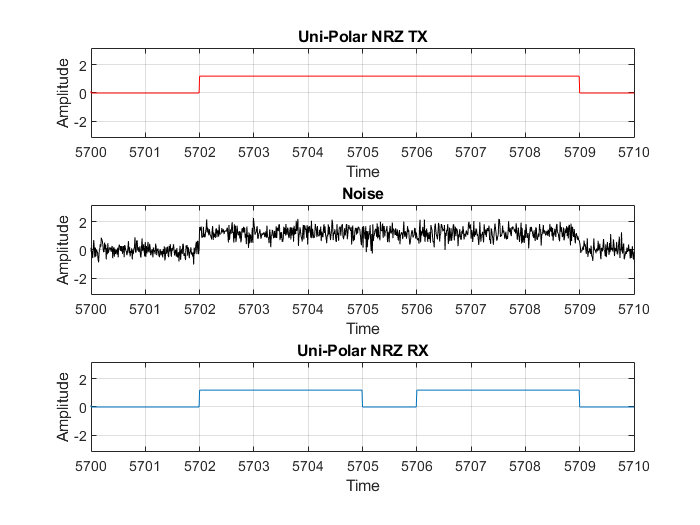

ERROR_Percentage = 6.6800

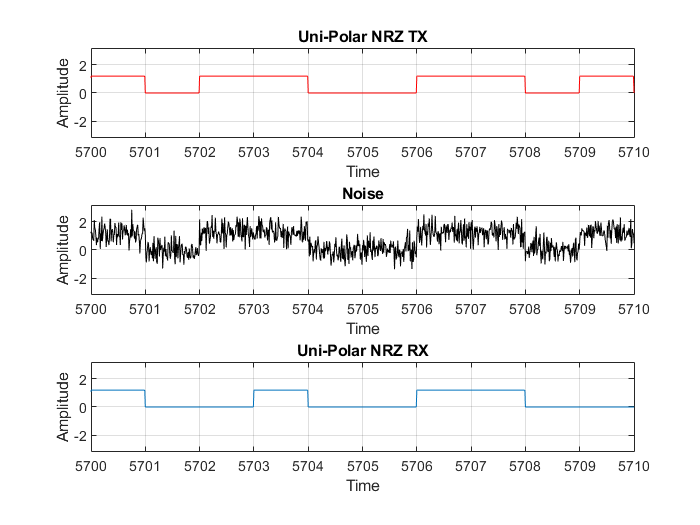

ERROR_Percentage = 13.0200

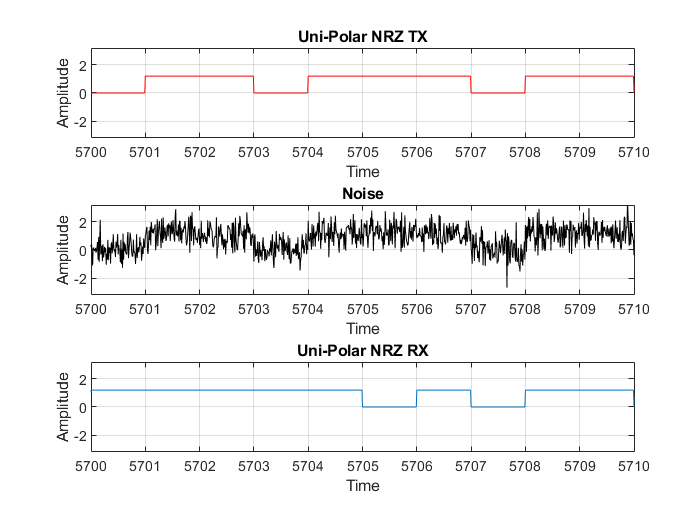

ERROR_Percentage = 18.0200

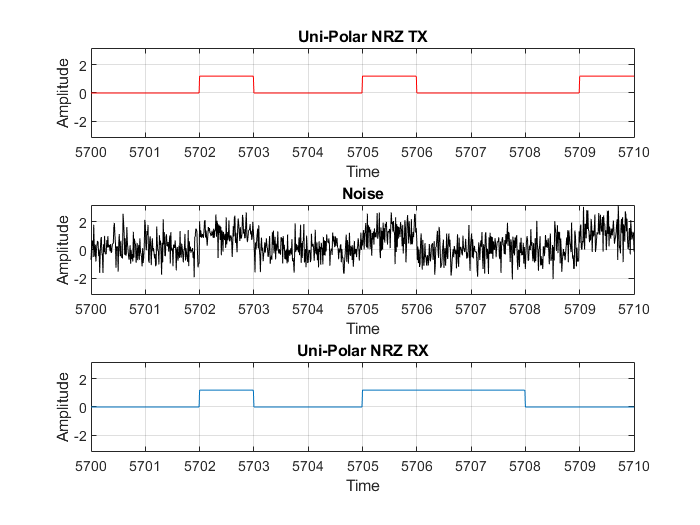

ERROR_Percentage = 23.3200

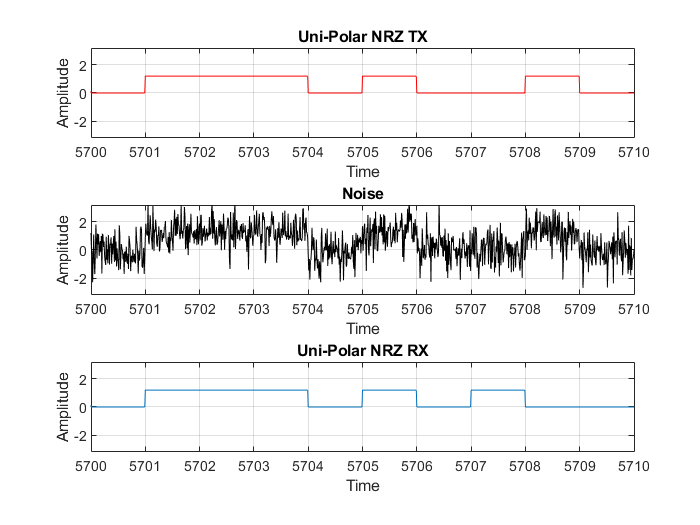

ERROR_Percentage = 26.8700

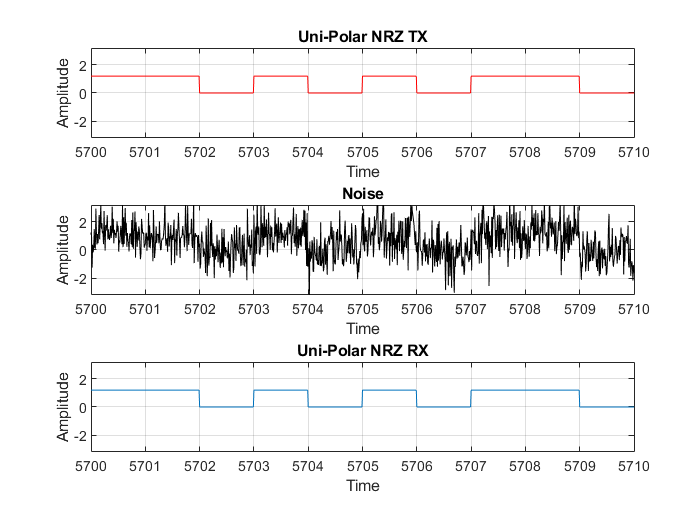

ERROR_Percentage = 28.5600

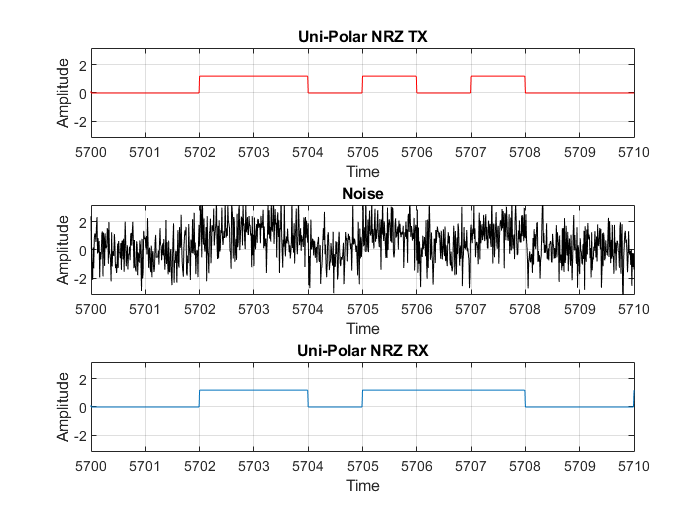

ERROR_Percentage = 31.1400

for o = 1 : 10
stream_of_bits = randi([0 1], 1, no_of_bits);
line_coding = stream_of_bits * vcc;

c = 0;
for i = 1:10000
    for j = 1 : 100
        TX_UP_NRZ(c + j) = line_coding(i); 
    end
    c = c + 100;
end
figure(o)
subplot(3,1,1)
plot(t, TX_UP_NRZ, 'r')
axis([0 length(TX_UP_NRZ) -(vcc + 2) (vcc + 2)]);
xlabel('Time');
ylabel('Amplitude');
title('Uni-Polar NRZ TX');
grid on;
xlim([5700 5710]);


noise = TX_UP_NRZ + sigma(o) * randn(size(TX_UP_NRZ));
subplot(3,1,2)
plot(t, noise, 'k')
axis([0 length(TX_UP_NRZ) -(vcc + 2) (vcc + 2)]);
xlabel('Time');
ylabel('Amplitude');
title('Noise');
grid on;
xlim([5700 5710]);

c = 0;
for i = 50 : 100 : length(TX_UP_NRZ)
    if(noise(i) >= 0.6)
        for k = 1 : 100
            RX_UP_NRZ(c + k) = vcc;
        end
    else
        for k = 1 : 100
            RX_UP_NRZ(c + k) = gnd;
        end
    end
    c = c +100;
end

subplot(3,1,3)
plot(t, RX_UP_NRZ)
axis([0 length(RX_UP_NRZ) -(vcc + 2) (vcc + 2)]);
xlabel('Time');
ylabel('Amplitude');
title('Uni-Polar NRZ RX');
grid on;
xlim([5700 5710]);
error = 0;
for i = 1 : length(RX_UP_NRZ)
    if(RX_UP_NRZ(i) == TX_UP_NRZ(i))
        continue
    else
        error = error + 1;
    end
end
ERROR_Percentage = error / no_of_bits
end